# System parameter calculutions

The goal of this script is to compute the dimensions of the various diemnsions of the parts of the 2 stage zero stiffness variable position and mass gravity compensation. It does so using the given constraints, prefrences and part selection 

### Material constants

clear all; close all;
g = 9.81; %[m/s^2]   gravity constant                     
E1 = 310E9; %[Pa]    elastic modulus of steel 
sigma_y = 220E6; %[Pa] yield stress steel

### System constants

m2 = .8; %[Kg] unloaded mass
m1 = m2 + 2; %[Kg] loaded mass
sys_angle = 28/180*pi; %[rad] angle at which the mirror is located 
t = 6e-3; %[m] thickness of plate material that will be used for construction

### Constraints

h_max = .4; %[m] maximal height mass compensator     
w_max  = .1; %[m] maximal width mass compensator   
sf = 1.1; %safety margin 10%

### Requirements

d_mirror = .16 

d_mirror = 0.1600

Longstroke = d_mirror*sin(sys_angle)*3 %[m] stroke of the first stage

Longstroke = 0.2253

S1 = Longstroke*sf

S1 = 0.2479

S1 = 170E-3

S1 = 0.1700

S2 = 5e-3

S2 = 0.0050

# First stage parameters

The first stage has and adjustment screw, clamp and spiral pulley, here it is desirable to have low stiffness of the spring such that the size of the spiral pulley can be minimized

### Variable parameters

R_i = 20E-3; %[m] inner radius -> constraint by material design of the pulley system
R_o = R_i*5 %[m] outer radius -> design prefrences to keep the system compact -> limited by the tickness of the legs of the system

R_o = 0.1000

R_o = 0 

R_o = 0.0529

n_rotations = S1/(2*pi*(R_i+R_o)/2) %estimation of the amount of rotations that the pulley needs to make 

n_rotations = 0.7423

F1 = m1*g; %[N] initial load on the system
F2 = m2*g; %[N] second loading condition
SR = 1/3; %spring elongation ratio
h_mech = h_max/20 %[m] height needed for the adjustment mechanism

h_mech = 0.0200

h_mech = 5*t% 5 plate material of space needed for construction

h_mech = 0.0300

### Spring Calculations

The path length of the spiral pulley is always shorter than the path length of the load with consant R_o because R_i < r R_o

Thus the elongation of the spring that will be needed is at most equal to our save_longstroke 

The total height of the system is at most 2*R0 + save_long_stroke + init_elongation <= max_height / sf

k1 = round( ((1+1/(1-SR) )*F1-F2)/(h_max-R_o-h_mech-S1/(1-SR)))

k1 = 979

h_adjust = (F1 - F2)/k1 %adjustment height

h_adjust = 0.0200

Lmax = h_max - R_o - h_adjust - h_mech %maximum length of the spring

Lmax = 0.2971

L_0 = Lmax*SR %initial length spring

L_0 = 0.0990

L1 = F1/k1 %initial elongation (without initial length)

L1 = 0.0281

L2 = F2/k1 %second elongation (without initial length)

L2 = 0.0080

R_o + S1 + L1 + L_0 + h_adjust + h_mech %check should be equal to maximal length

ans = 0.4000

### Spiral pulley

F_0 = F1;

F_0 = 27.4680

k = k1;

k = 979

r1 = R_i;

r1 = 0.0200

r2 = F_0/k;

r2 = 0.0281

S = F_0*r2/k;

S = 7.8721e-04

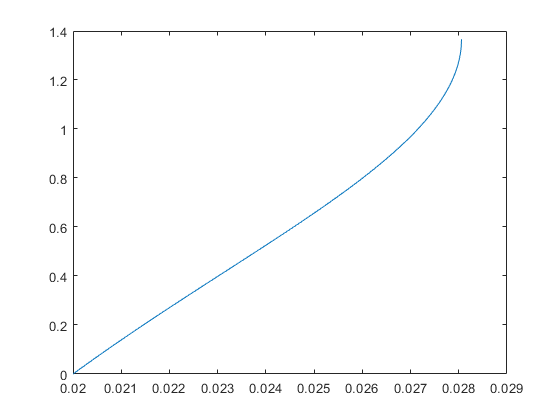

T = F_0*r2/(k*r1);
n_steps = 1000;
stepsize = (r2- r1)/n_steps;
r = [r1:stepsize:r2];
theta = -sqrt(S^2- r.^4)./(2*r.^2) + 0.5 *asin(r.^2/S) ;
const = theta(1);
theta = theta - const; %adding constant such that theta(1) = 0
theta(r > sqrt(S)) = angle(theta(r > sqrt(S)));

figure()
clf
plot(r,theta)

### Plotting shape

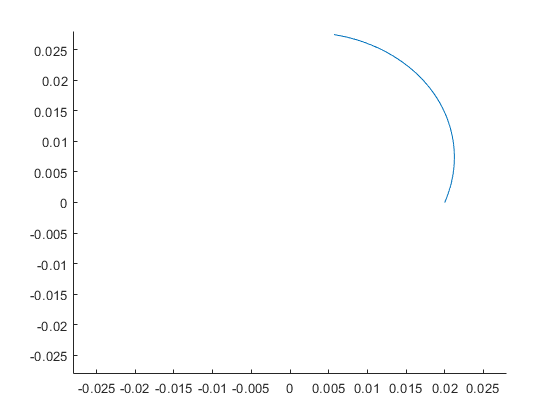

x = real(cos(theta).*r);
y = real(sin(theta).*r);
figure()
clf
hold on
plot(x,y)
plot(0,0)
xlim([-r2,r2])
ylim([-r2,r2])

# Second stage parameters

R = 0.9; %stiffness reduction
n = 2; %number of leaf springs
h2 = h_max -2*R_o - S1 %second stage maximal height

h2 = 0.0300

h2 = round(h2,1); %rounding to 
h2*1e3

ans = 0


h2n = 8*S2; %for the negative spring we need about 3 times more than the stroke 
h2p = h2 - h2n;
h2n*1e3

ans = 40

round(h2p*1e3)

ans = -40

### Positive spring design

%spring ratio SR is previously assigned
hm2p = h2p/4 %mechnism height needed for construction

hm2p = -0.0100

kp = round( ((1+1/(1-SR) )*F1-F2)/(h2p-hm2p-S2/(1-SR)))

kp = -1622

ha2p = (F1 - F2)/kp %possible height adjustment 

ha2p = -0.0121

stroke = 1 / (1- R)*ha2p %possible output stroke with current adjustment methdod (excl mass adjustment) (most of this stroke goes to mass adjustment)

stroke = -0.1210

Lmax = h2p - ha2p - hm2p; %maximum length of the spring
L_0 = Lmax*SR; %initial length spring
L1 = F1/kp; %initial elongation (without initial length)
L2 = F2/kp; %second elongation (without initial length)
hm2p + ha2p + L_0 + L1 + S2 %should be equal to the 

ans = -0.0400

### Negative spring design

n = 2; %number of buckled leaf springs
sm = 0.87; %safety margin on operation range buckled leaf spring
kn = round(kp*R) %desired negative spring stiffness

kn = -1460

t = 1e-3; %[m] thickness plate steel
b = R_o * 1/4

b = 0.0250

b*1e3

ans = 25

#### Viability short stroke 

L_desired = ( ( (S2/sm)^2 * 53 * E1 *t)/(sigma_y*5/3) )^(1/3) %leaf spring length given the desired stroke 

L_desired = 0.1140

I = t^3*b/12; %[m^4]  moment of inertia leaf spring
%Cx = 44.4*E1*I/L^3 * n %total stiffness dependand on number of leaf springs
L = ((44.4*E1*I*n)/kn)^(1/3); %desired length given desired stiffness 
L = round(L,3) %rounding the length

L = 0.1700 + 0.2940i

Cx = round(44.4*E1*I/L^3 * n ) %total stiffness dependand on number of leaf springs

Cx = -1.4640e+03 - 3.0000e+00i

lw = L/t %thickness ratio 

lw = 1.7000e+02 + 2.9400e+02i

uz_max = sigma_y*L^2/(53*E1*t); %[m] max compression in z direction leaf spring
uz_max * 1e3 %[mm]

ans = -0.7704 + 1.3385i

ux = sm * sqrt(5/3*uz_max*L); %[m] max stroke of springs with safety margin
ux*1e3 %[mm]

ans = 0.0255 + 25.7223i

# Final results

kp - Cx %final stiffness

ans = -1.5800e+02 + 3.0000e+00i

R_actual = round(Cx/kp,2) %actual reduction ratio is different due to rounding

R_actual = 0.9000